clear all; clc; close all;

cd('/home/millieginty/Documents/git-repos/EMMA/analysis/MATLAB/'); %---home computer
% cd('C:\Users\ravindra\Desktop\Ravindra_s_docs\ICP_data_QA_QC\pca_matlab_work'); %---laptop
%cd(); %---office computer

%%%%%%%%%%%%%%%%%%%%%%%%%%% load the PCA data for the three sites %%%%%%%%%
site_Q_maj_ion_data=load('Data_for_EMMA_2022_HB.txt');
% .txt data want to be saved as tab delimited file

%----format of the above three files is:
%---col(1): Event number
%---col(2): Cl (mg/L)
%---col(3): SO4-S (mg/L)
%---col(4): NO3-N (mg/L)
%---col(5): PO4-P (mg/L)
%---col(6): dD
%---col(7): d18O
%---col(8): "Al (mg/L)"
%---col(9): "Ca (mg/L)"
%---col(10): "Cu (mg/L)"
%---col(11): "Fe (mg/L)"
%---col(12): "K (mg/L)"
%---col(13): "Mg (mg/L)"
%---col(14): "Mn (mg/L)"
%---col(15): "Na (mg/L)"
%---col(16): "P (mg/L)"
%---col(17): "Zn (mg/L)"
%---col(18): "Si (mg/L)"
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[m1,n1]=size(site_Q_maj_ion_data);

%%%%%%%%%%%%%% STEP 1:  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%% plotting section for solute-solute plots %%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fs_leg=10; %---font size for legends--
fs_lab=10;%---font size for x and y, labels and titles--
mark_size_fact=0.5;
rgb_peru=[1.0000,0.6445,0];       %---color for dry (index 3) season--
rgb_red=[1,0,0];                       %---color for summer (index 4) season--
rgb_royal_blue=[0.2539,0.4102,0.8789]; %---color for winter and snowmelt (index 1 and 2) season--
rgb_purple=[0.2930,0,0.5078];          %---color for end-members

rgb_E1=rgb('MediumBlue');
rgb_E2=rgb('Green');
rgb_E3=rgb('Red');
rgb_E4=rgb('DarkOrange');
rgb_E5=rgb('Black');
rgb_E6=rgb('Yellow');

%rgb_winter=rgb('MediumBlue');
%rgb_spring=rgb('Green');
%rgb_summer=rgb('Red');
%rgb_fall=rgb('DarkOrange');
fs_leg=11; %---font size for legends--

%%%%%%%%%%%%%%%%%%%%%%%% solute-solute plot for all solutes %%%%%%%%%%%%%%

ele_int_P17=  [2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18];

%---col(2): Cl (mg/L)
%---col(3): SO4-S (mg/L)
%---col(4): NO3-N (mg/L)
%---col(5): PO4-P (mg/L)
%---col(6): dD
%---col(7): d18O
%---col(8): "Al (mg/L)"
%---col(9): "Ca (mg/L)"
%---col(10): "Cu (mg/L)"
%---col(11): "Fe (mg/L)"
%---col(12): "K (mg/L)"
%---col(13): "Mg (mg/L)"
%---col(14): "Mn (mg/L)"
%---col(15): "Na (mg/L)"
%---col(16): "P (mg/L)"
%---col(17): "Zn (mg/L)"
%---col(18): "Si (mg/L)"

txt_lab_compl={'Cl','SO4-S','NO3-N','PO4-P','dD','d18O','Al','Ca','Cu','Fe','K','Mg','Mn','Na','P','Zn','Si'};

X_solute_mat0_1=zeros(m1,length(ele_int_P17));
all_sol_seas_ind=NaN(m1,1);
all_sol_seas_ind=site_Q_maj_ion_data(:,1);  %--get the event number

for i1=1:length(ele_int_P17)
    X_solute_mat0_1(:,i1)=site_Q_maj_ion_data(:,ele_int_P17(1,i1));
end

figure(1);
X_solute_mat3=X_solute_mat0_1;
[m_sol3,n_sol3]=size(X_solute_mat3);

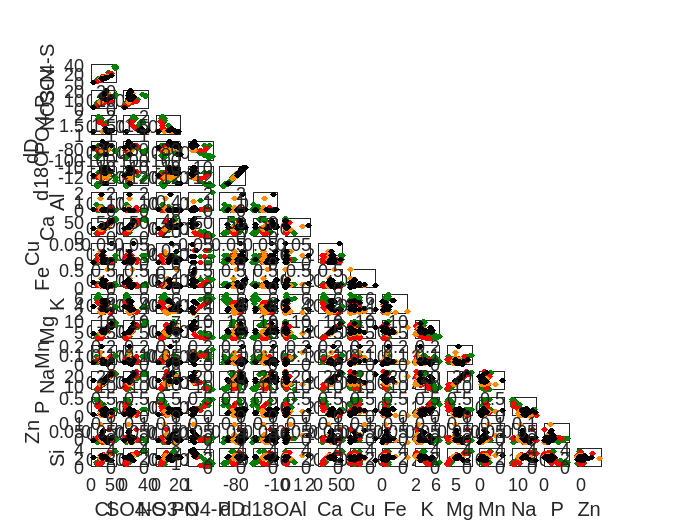

count_p=17-1;  %---point of change----------

x1_vec=zeros(m_sol3,1);
y1_vec=zeros(m_sol3,1);

tic; %--start the timer

for j1=1:n_sol3
    x1_vec=X_solute_mat3(:,j1);
    %     j1,txt_lab(1,j1)
    %     xlabel(txt_lab(1,j1));
    %      count_p=6;
    for i1=1:n_sol3
        if i1>j1
            y1_vec=X_solute_mat3(:,i1);
            subplot(length(ele_int_P17),length(ele_int_P17),i1+j1-1+count_p);
            %---color code the values
            if all_sol_seas_ind(1,1)==1 %---for event 1
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E1,'MarkerEdgeColor',rgb_E1);
            elseif all_sol_seas_ind(1,1)==2 %---for event 2
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E2,'MarkerEdgeColor',rgb_E2);
            elseif all_sol_seas_ind(1,1)==3 %---for event 3
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E3,'MarkerEdgeColor',rgb_E3);
            elseif all_sol_seas_ind(1,1)==4 %---for event 4
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E4,'MarkerEdgeColor',rgb_E4);
            elseif all_sol_seas_ind(1,1)==5 %---for event 5
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E5,'MarkerEdgeColor',rgb_E5);
            elseif all_sol_seas_ind(1,1)==6 %---event 6
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E6,'MarkerEdgeColor',rgb_E6);
            end
            hold on;
            for k1=2:size(x1_vec,1)
                if all_sol_seas_ind(k1,1)==1 %---for E1
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E1,'MarkerEdgeColor',rgb_E1);
                elseif all_sol_seas_ind(k1,1)==2 %---for E2
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E2,'MarkerEdgeColor',rgb_E2);
                elseif all_sol_seas_ind(k1,1)==3 %---for E3
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E3,'MarkerEdgeColor',rgb_E3);
                elseif all_sol_seas_ind(k1,1)==4 %---for E4
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E4,'MarkerEdgeColor',rgb_E4);
                elseif all_sol_seas_ind(k1,1)==5 %---for E5
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E5,'MarkerEdgeColor',rgb_E5);
                elseif all_sol_seas_ind(k1,1)==6 %---for E6
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E6,'MarkerEdgeColor',rgb_E6);
                end
            end
            
            hold off;
            
            %            xlabel(txt_lab(1,j1));
            %ylabel(txt_lab(1,i1));
            if i1==n_sol3
                xlabel(txt_lab_compl(1,j1));
            end
            if j1==1
                ylabel(txt_lab_compl(1,i1));
            end
            %            ylabel(txt_lab2(i1,1),'fontsize',5);
            %            xlabel(txt_lab(1,j1),'fontsize',5);
            count_p=count_p+n_sol3-1;
            fig = gcf;
            set(gca,'fontsize',0.4*fs_leg);
            %            set(gca,'Xtick',[]);
            %            set(gca,'Ytick',[]);
        end
        fig = gcf;
        set(gca,'fontsize',1*fs_leg);
        
    end
    count_p=(j1+1)*(n_sol3-1);
    fig = gcf;
    set(gca,'fontsize',1*fs_leg);
end

fig = gcf;
set(gca,'fontsize',1*fs_leg);

fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 16 9];
%print('-f1','C:\Users\mat\Desktop\')
%---------------------------solute-solute plot section ends here ----------

toc

Elapsed time is 63.660689 seconds.




%%%%%%%%%%%%%%%%%%% remove the NaN values  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_conser_solutes=6;  %----this values comes from the bivariate solute-solute plots when considering all solute pairs
%--SO4-S (3), dD(6), d18O(7), Ca(9), Mg(13), Na(15)

site_Q_maj_ion_data_v2=NaN(m1,num_conser_solutes+1); %--it has only conservative solutes
%---format of the above file is:
%---col(1):  event number
%---col(2):  SO4-S(mg/L)
%---col(3):  dD
%---col(4):   d18O
%---col(5): Ca (mg/L)
%---col(6): Mg (mg/L)
%---col(7): Na (mg/L)

site_Q_maj_ion_data_v2(:,1)=site_Q_maj_ion_data(:,1);
site_Q_maj_ion_data_v2(:,2)=site_Q_maj_ion_data(:,3);
site_Q_maj_ion_data_v2(:,3)=site_Q_maj_ion_data(:,6);
site_Q_maj_ion_data_v2(:,4)=site_Q_maj_ion_data(:,7);
site_Q_maj_ion_data_v2(:,7)=site_Q_maj_ion_data(:,9);
site_Q_maj_ion_data_v2(:,5)=site_Q_maj_ion_data(:,13);
site_Q_maj_ion_data_v2(:,6)=site_Q_maj_ion_data(:,15);


%---observed data-only containing the chemistry data--

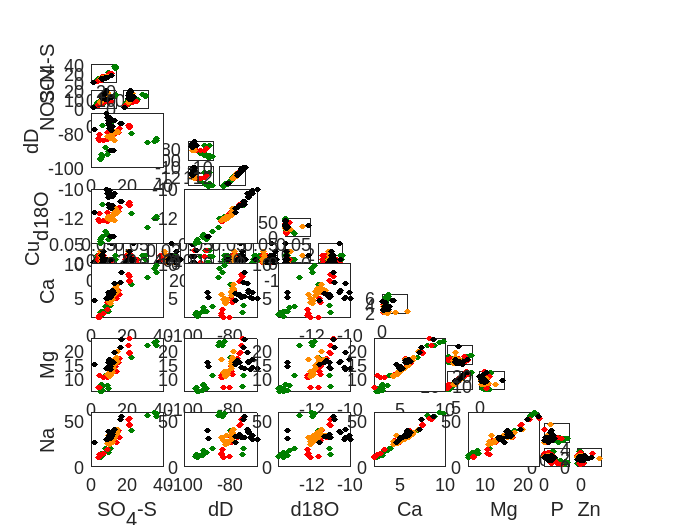

[m2,n2]=size(site_Q_maj_ion_data_v2);

mean_std_arr=zeros(5,n2);
%---row (1): sample mean
%---row (2): sample stdev
%---row (3): sample coefficeint of variation
%---row (4): sample min
%---row (5): sample max

for i0=1:n2
    mean_std_arr(1,i0)= mean(site_Q_maj_ion_data_v2(:,i0));%-----compute mean---
    mean_std_arr(2,i0)= std(site_Q_maj_ion_data_v2(:,i0)); %-----compute standard deviation---
    mean_std_arr(3,i0)=mean_std_arr(2,i0)/mean_std_arr(1,i0);
    %-----compute coefficient of variation as the ratio of standard deviation over mean---
    mean_std_arr(4,i0)=min(site_Q_maj_ion_data_v2(:,i0));%-----compute min---
    mean_std_arr(5,i0)=max(site_Q_maj_ion_data_v2(:,i0));%-----compute max---
end

mean_std_arr(:,1)=NaN;

site_Q_maj_ion_data_v3 = site_Q_maj_ion_data_v2(all(~isnan(site_Q_maj_ion_data_v2),2),:); %---remove missing values from the observed data containing only chemistry data ---

site_Q_maj_ion_data_v4=site_Q_maj_ion_data_v3; %---this matrix has z-score values
%---format of the above file is:
%---col(1): event number
%---col(2): standardized SO4-S(mg/L)
%---col(3): standardized  dD
%---col(4): standardized  d18O
%---col(5): standardized  Ca (mg/L)
%---col(6): standardized  Mg (mg/L)
%---col(7): standardized  Na (mg/L)

[m3,n3]=size(site_Q_maj_ion_data_v3);

for i1=1:size(site_Q_maj_ion_data_v3,1)
    for j1=2:size(site_Q_maj_ion_data_v3,2)
        if ~isnan(site_Q_maj_ion_data_v3(i1,j1))
            site_Q_maj_ion_data_v4(i1,j1)=(site_Q_maj_ion_data_v3(i1,j1)-mean_std_arr(1,j1))/mean_std_arr(2,j1);
        else
            site_Q_maj_ion_data_v4(i1,j1)=NaN;
        end
    end
end




site_Q_maj_ion_data_v5=NaN(size(site_Q_maj_ion_data_v3,1),size(site_Q_maj_ion_data_v3,2)-1);
site_Q_maj_ion_data_v6=NaN(size(site_Q_maj_ion_data_v4,1),size(site_Q_maj_ion_data_v4,2)-1);

site_Q_maj_ion_data_v5=site_Q_maj_ion_data_v3(:,2:end);
%---format of the above file is:
%---col(1):  SO4-S(mg/L)
%---col(2):   dD
%---col(3):  d18O
%---col(4):  Ca (mg/L)
%---col(5):  Mg (mg/L)
%---col(6):  Na (mg/L)

site_Q_maj_ion_data_v6=site_Q_maj_ion_data_v4(:,2:end);
%---format of the above file is:
%---col(1): standardized SO4-S(mg/L) for v4 file
%---col(2): standardized  dD
%---col(3): standardized  d18O
%---col(4): standardized  Ca (mg/L)
%---col(5): standardized  Mg (mg/L)
%---col(6): standardized  Na (mg/L)

%%%%%%%%%%%%%%%%%% for conservative tracers only %%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% solute-solute plot for only conservative solutes begins here %%%%%%%%%%%%%%%%%%%%%%
ele_int_P6=  [  2,      3,     4,    5,    6,    7 ];
% %----------   SO4-S,  dD,  d18O,  Ca,   Mg,  Na------
txt_lab_02={'SO_{4}-S','dD','d18O','Ca','Mg','Na'};
txt_lab_02={'SO_{4}-S','dD','d18O','Ca','Mg','Na'};

X_solute_mat0_2=zeros(m3,length(ele_int_P6));

all_sol_seas_ind0_2=NaN(m3,1);
all_sol_seas_ind0_2=site_Q_maj_ion_data_v3(:,1);  %--get the event number

for i1=1:length(ele_int_P6)
    X_solute_mat0_2(:,i1)=site_Q_maj_ion_data_v3(:,ele_int_P6(1,i1));
end


figure(2);
X_solute_mat5=X_solute_mat0_2;
[m_sol4,n_sol4]=size(X_solute_mat5);

count_p_0_2=6-1;               %---point of change

x1_vec=zeros(m_sol4,1);
y1_vec=zeros(m_sol4,1);

for j1=1:n_sol4
    x1_vec=X_solute_mat5(:,j1);
    %     j1,txt_lab(1,j1)
    %     xlabel(txt_lab(1,j1));
    %      count_p=6;
    for i1=1:n_sol4
        if i1>j1
            y1_vec=X_solute_mat5(:,i1);
            subplot(length(ele_int_P6),length(ele_int_P6),i1+j1-1+count_p_0_2);
            %---color code the values
            if all_sol_seas_ind0_2(1,1)==1 %---for event 1
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E1,'MarkerEdgeColor',rgb_E1);
            elseif all_sol_seas_ind0_2(1,1)==2 %---for event 2
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E2,'MarkerEdgeColor',rgb_E2);
            elseif all_sol_seas_ind0_2(1,1)==3 %---for event 3
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E3,'MarkerEdgeColor',rgb_E3);
            elseif all_sol_seas_ind0_2(1,1)==4 %---for event 4
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E4,'MarkerEdgeColor',rgb_E4);
            elseif all_sol_seas_ind0_2(1,1)==5 %---for event 5
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E5,'MarkerEdgeColor',rgb_E5);
            elseif all_sol_seas_ind0_2(1,1)==6 %---for event 6
                plot(x1_vec(1,1),y1_vec(1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E6,'MarkerEdgeColor',rgb_E6);
            end
            
            
            hold on;
            
            for k1=2:size(x1_vec,1)
                if all_sol_seas_ind0_2(k1,1)==1 %---for event 1
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E1,'MarkerEdgeColor',rgb_E1);
                elseif all_sol_seas_ind0_2(k1,1)==2 %---for event 2
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E2,'MarkerEdgeColor',rgb_E2);
                elseif all_sol_seas_ind0_2(k1,1)==3 %---for event 3
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E3,'MarkerEdgeColor',rgb_E3);
                elseif all_sol_seas_ind0_2(k1,1)==4 %---for event 4
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E4,'MarkerEdgeColor',rgb_E4);
                elseif all_sol_seas_ind0_2(k1,1)==5 %---for event 5
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E5,'MarkerEdgeColor',rgb_E5);
                elseif all_sol_seas_ind0_2(k1,1)==6 %---for event 6
                    plot(x1_vec(k1,1),y1_vec(k1,1),'o','Linewidth',2,'MarkerSize',2,'MarkerFaceColor',rgb_E6,'MarkerEdgeColor',rgb_E6);
                    
                end
            end
            
            hold off;
            
            %            xlabel(txt_lab(1,j1));
            %ylabel(txt_lab(1,i1));
            if i1==n_sol4
                xlabel(txt_lab_02(1,j1));
            end
            if j1==1
                ylabel(txt_lab_02(1,i1));
            end
            %            ylabel(txt_lab2(i1,1),'fontsize',5);
            %            xlabel(txt_lab(1,j1),'fontsize',5);
            count_p_0_2=count_p_0_2+n_sol4-1;
            fig = gcf;
            set(gca,'fontsize',0.4*fs_leg);
            %            set(gca,'Xtick',[]);
            %            set(gca,'Ytick',[]);
        end
        fig = gcf;
        set(gca,'fontsize',1*fs_leg);
        
    end
    count_p_0_2=(j1+1)*(n_sol4-1);
    fig = gcf;
    set(gca,'fontsize',1*fs_leg);
end

fig = gcf;
set(gca,'fontsize',1*fs_leg);

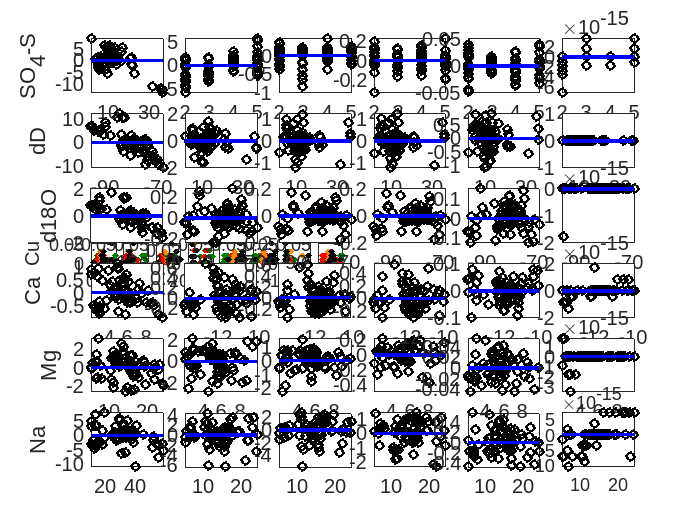

fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 16 9];

% print('-f2','C:\Users\ravindra\Desktop\HB_PB_WB_master_datafiles\matlab_work\pca_work\Figures\CC_plot_all_conserv_solus_WB','-dpng','-r600')

%%%%%%%%% solute-solute plot for only conservative solutes ends here %%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%% perform the PCA analysis now %%%%%%%%%%%%%%%%%%%%%%%%%%
% [coeff,score,latent,~,explained,~] = pca(inter_data_pca2,'rows','complete');
[coeff2,score2,latent2,~,explained2,~] = pca(site_Q_maj_ion_data_v6,'Centered',false);
%[coeff,score,latent,~,explained,~] = pca(inter_data_pca2,'algorithm','als','Centered',false);
% [coeff,score,latent,tsquare] = princomp(zscore(inter_data_pca2));
%----each column of coeff contains an eigen vector----
%----each row of score contains projection of an observation on each of the principal component space (listed by columns) here ----
%----each row of the latent contains the eigen values of the standardized
%solute concentration matrix
%---each row of the explained matix contians the % variace that can be
%explained by retaining an eigen vector (listed here in the descening order
%of the eigen values)----

explained2_cumul=explained2;
sum_1=0;

for i1=1:length(explained2)
    sum_1=sum_1+explained2_cumul(i1,1);
    explained2_cumul(i1,1)=100*sum_1/sum(explained2);
end

eig_greater_one=sum((latent2>=1));
[m4,n4]=size(coeff2);

mat_eig_val_var_Exp=NaN(size(latent2,1),3);
%--format of the above file is:
%--col(1): eig values
%--col(2): number of eigen vectors retained
%--col(3): % cumulative variance explained
mat_eig_val_var_Exp(:,1)=latent2;
mat_eig_val_var_Exp(:,2)=1:size(latent2,1);
mat_eig_val_var_Exp(:,3)=explained2_cumul;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eig_vals_con=size(latent2,1); %eig_greater_one+1;  %---


eig_mat_cell={eig_vals_con,7};
%---format of the above cell is:
%-(1)--: number of eigen vectors retained
%-(2)--: matrix of eigen vectors m x p ; where m: is the total number of eigenvectors retained, p is the number of solutes----
%-(3)--: predicted concentrations in the solute space---
%-(4)--: Error matrix, modeled - prediction
%-(5)--: A matrix at each number of retained eigen vectors which contains:
%--(column 1): slope
%--(column 2): R-value
%--(column 4): p-value at 95% confidence limit
%--(column 5): bias
%--(column 6): RRMSE



x1_mat=zeros(size(site_Q_maj_ion_data_v6));
x2_mat=x1_mat;
x3_mat=x1_mat;
x4_mat=x1_mat;

mat_sl_RPbi_rrmse=zeros(5,m4);
%--format of the above file is:
%--(row 1): slope
%--(row 2): R-value
%--(row 3): p-value at 95% confidence limit
%--(row 4): bias
%--(row 5): RRMSE

a1=0; b1=0; c1=0; d1=0; e1=0;
Obs_mod_mat=zeros(m3,2);
mean_std_arr_v2=mean_std_arr(:,2:end);

for i3=1:eig_vals_con
    eig_mat_cell{i3,1}=i3; %----number of eigen vectors retained-----------
    V_mat=zeros(i3,m4);
    [coeff3,score3,latent3,~,explained3,~] = pca(site_Q_maj_ion_data_v6,'Centered',false,'NumComponents',i3);
    %[coeff3,score3,latent3,~,explained3,~] = pca(inter_data_pca4,'Centered',true,'NumComponents',i3);
    V_mat=coeff3';
    eig_mat_cell{i3,2}=V_mat; %-----this is the V matrix of the k by p size, where k is
    %the number of retianed eigen vecotrs and p is the number of solutes
    x1_mat= site_Q_maj_ion_data_v6*(V_mat')*(inv(V_mat*V_mat'))*V_mat; %---this is the X_star_hat matrix (Hooper 2003 convention)
    
    for j1=1:n4
        x2_mat(:,j1)= mean_std_arr_v2(1,j1)+x1_mat(:,j1)*(mean_std_arr_v2(2,j1));    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
    
    eig_mat_cell{i3,3}= x2_mat; %-----this is the predicted concentrations in the solute space-----
    x3_mat=x2_mat-site_Q_maj_ion_data_v5;  %----this is the error matrix----
    eig_mat_cell{i3,4}=x3_mat;
    
    
    for k1=1:m4
        Obs_mod_mat=zeros(size(site_Q_maj_ion_data_v5,1),2);
        Obs_mod_mat(:,1)=site_Q_maj_ion_data_v5(:,k1);
        Obs_mod_mat(:,2)=x3_mat(:,k1);
        [a1,b1,c1,d1,e1]=function_sl_R_P_bi_RRMSE(Obs_mod_mat,-1);
        mat_sl_RPbi_rrmse(1,k1)=a1;
        mat_sl_RPbi_rrmse(2,k1)=b1;
        mat_sl_RPbi_rrmse(3,k1)=c1;
        mat_sl_RPbi_rrmse(4,k1)=d1;
        mat_sl_RPbi_rrmse(5,k1)=e1;
        
    end
    eig_mat_cell{i3,5}=mat_sl_RPbi_rrmse';
    %----format of the above cell is:
    %--format of the above file is:
    %--(column 1): slope
    %--(column 2): R-value
    %--(column 3): p-value at 95% confidence limit
    %--(column 4): bias
    %--(column 5): RRMSE
end


%%%%%%%%%%%%%%%%%%%%%% create the residual plots at various number of retained eigen vectors %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(3);
ind_c=0;
a_mat=zeros(m2,1);
b_mat=zeros(m2,1);
c_mat=zeros(m2,1);
sl_p_vec=zeros(1,2);

count_4=0;
eig_to_plot=eig_vals_con;  %---modify this

for i4=1:eig_to_plot  %%%%%%%%%%%%%%%%% this is the %modification line%%%%%%%%%%%%%%%%%%%
    count_4=0;
    if i4==1
        for j4=1:length(ele_int_P6)
            ind_c=j4; %ele_int_P5(1,j4);
            sl_p_vec=zeros(1,2);
            a_mat=eig_mat_cell{i4,4}(:,ind_c);
            b_mat=site_Q_maj_ion_data_v5(:,ind_c);
            c_mat=linspace(nanmin(b_mat),nanmax(b_mat),10);
            sl_p_vec(1,1)=eig_mat_cell{i4,5}(ind_c,1);
            sl_p_vec(1,2)=eig_mat_cell{i4,5}(ind_c,3);
            h1(i4+count_4)=subplot(length(ele_int_P6),eig_to_plot,i4+count_4);
            h1=plot(b_mat,a_mat,'ok','LineWidth',2,'MarkerSize',10*mark_size_fact); hold on;   %'MarkerFaceColor','b'
            plot(c_mat,c_mat*0,'-b','LineWidth',2); hold off;
            xlim([nanmin(b_mat),nanmax(b_mat)])
            %title(sprintf('p-value= %0.2f',sl_p_vec(1,2)));
            fig = gcf;
            set(gca,'fontsize',12);
            ylabel(txt_lab_02{1,j4});
            count_4=count_4+eig_to_plot;
        end
    else
        for j4=1:length(ele_int_P6)
            ind_c=j4; %ele_int_P5(1,j4);
            sl_p_vec=zeros(1,2);
            a_mat=eig_mat_cell{i4,4}(:,ind_c);
            b_mat=site_Q_maj_ion_data_v3(:,ind_c);
            c_mat=linspace(nanmin(b_mat),nanmax(b_mat),10);
            sl_p_vec(1,1)=eig_mat_cell{i4,5}(ind_c,1);
            sl_p_vec(1,2)=eig_mat_cell{i4,5}(ind_c,3);
            subplot(length(ele_int_P6),eig_to_plot,i4+count_4);
            h1=plot(b_mat,a_mat,'ok','LineWidth',2,'MarkerSize',10*mark_size_fact); hold on;   %'MarkerFaceColor','b'
            plot(c_mat,c_mat*0,'-b','LineWidth',2); hold off;
            xlim([nanmin(b_mat),nanmax(b_mat)])
            %legend(h1,sprintf('p-value= %0.2f',sl_p_vec(1,2)),'Location','northwest');
            fig = gcf;
            set(gca,'fontsize',12);
            count_4=count_4+eig_to_plot;
        end
    end
    
end

%h1(1,1)=ylabel('X');
% txt_lab={'Cl','SO4','Na','Mg','Si','K','Ca','Sr','Mo','\delta^{2}H'};
%
% for i2 = 1:length(AX)
%     ylabel(AX(i2,1),txt_lab{i2},'Fontsize',fs_lab);
%     xlabel(AX(end,i2),txt_lab{i2},'Fontsize',fs_lab);
% end

fig = gcf;
set(gca,'fontsize',1.0*fs_leg);

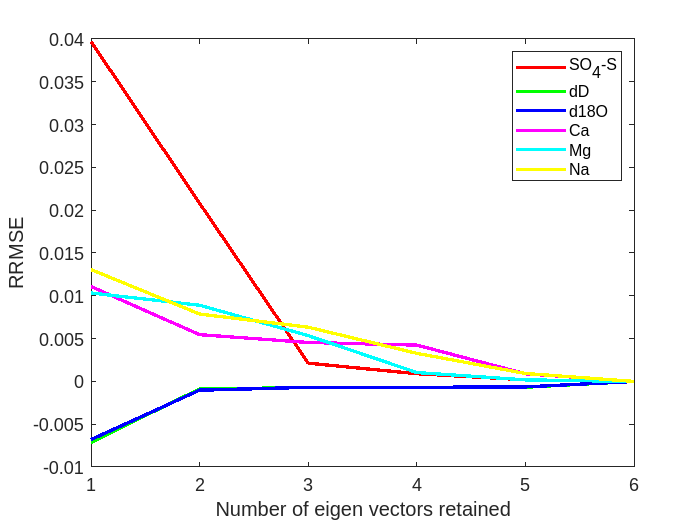

fig.PaperUnits = 'inches';
fig.PaperPosition = [0 0 16 9];


% print('-f3','C:\Users\ravindra\Desktop\HB_PB_WB_master_datafiles\matlab_work\pca_work\Figures\ND_solute_res_plot_WB','-dpng','-r600')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% create the RRMSE plots at various retained eigen vectors %%%%%

ind_SO4=1;
ind_dD=2;
ind_d18O=3;
ind_Ca=4;
ind_Mg=5;
ind_Na=6;

num_solutes=6;

RRMSE_mat_eig_ret=NaN(eig_vals_con,1+num_solutes);
%---format of the above file is:
%--col(1): eigen vectors retained
%--col(2): RRMSE for SO4
%--col(3): RRMSE for dD
%--col(4): RRMSE for d18O
%--col(5): RRMSE for Ca
%--col(6): RRMSE for Mg
%--col(7): RRMSE for Na


RRMSE_mat_eig_ret(:,1)=1:eig_vals_con;
R_mat=RRMSE_mat_eig_ret;
P_val_mat=R_mat;

ind_c=5;  %---for RRMSE---
for i5=1:eig_vals_con
    ind_c1=5;  %---for RRMSE---
    RRMSE_mat_eig_ret(i5,(1+1):(1+num_solutes))=[eig_mat_cell{i5,5}(ind_SO4,ind_c1),eig_mat_cell{i5,5}(ind_dD,ind_c1),eig_mat_cell{i5,5}(ind_d18O,ind_c1),eig_mat_cell{i5,5}(ind_Ca,ind_c1),eig_mat_cell{i5,5}(ind_Mg,ind_c1),eig_mat_cell{i5,5}(ind_Na,ind_c1)];
    
    ind_c2=2;  %---for R value --
    R_mat(i5,(1+1):(1+num_solutes))=[eig_mat_cell{i5,5}(ind_SO4,ind_c2),eig_mat_cell{i5,5}(ind_dD,ind_c2),eig_mat_cell{i5,5}(ind_d18O,ind_c2),eig_mat_cell{i5,5}(ind_Ca,ind_c2),eig_mat_cell{i5,5}(ind_Mg,ind_c2),eig_mat_cell{i5,5}(ind_Na,ind_c2)];
    
    ind_c3=3;  %---for P-value  --
    P_val_mat(i5,(1+1):(1+num_solutes))=[eig_mat_cell{i5,5}(ind_SO4,ind_c3),eig_mat_cell{i5,5}(ind_dD,ind_c3),eig_mat_cell{i5,5}(ind_d18O,ind_c3),eig_mat_cell{i5,5}(ind_Ca,ind_c3),eig_mat_cell{i5,5}(ind_Mg,ind_c3),eig_mat_cell{i5,5}(ind_Na,ind_c3)];
end

R_sq_mat=R_mat;

for i6=2:size(R_mat,2)
    for j5=1:size(R_mat,1)
        R_sq_mat(j5,i5)=R_mat(j5,i5)^2;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(4); %---RRMSE plot

plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,2),'-r','Linewidth',2); hold on;
plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,3),'-g','Linewidth',2);
plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,4),'-b','Linewidth',2);
plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,5),'-m','Linewidth',2);
plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,6),'-c','Linewidth',2);
plot(RRMSE_mat_eig_ret(:,1),RRMSE_mat_eig_ret(:,7),'-y','Linewidth',2); hold off;

xlabel('Number of eigen vectors retained');
ylabel('RRMSE');
xticks([1,2,3,4,5,6]);
legend('SO_{4}-S','dD','d18O','Ca','Mg','Na');
fig = gcf;
set(gca,'fontsize',1.0*fs_leg);

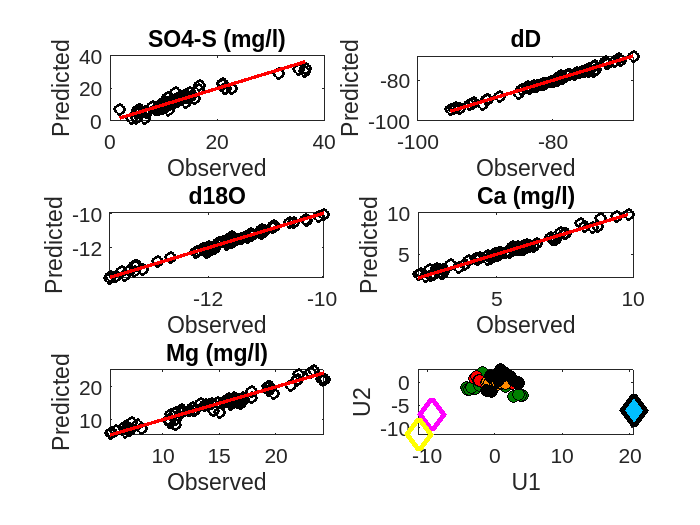


% print('-f4','C:\Users\ravindra\Desktop\HB_PB_WB_master_datafiles\matlab_work\pca_work\Figures\RRMSE_eig_retained_plot_WB','-dpng','-r600')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%% end-member part when considering all potenital EMs -begins here %%%%%%%%%%%%%%%%%%%%%%%% %%%%%


mark_size_val=15;
mark_size_fact=0.5;
fs_text=13;
EM_size_marker=14;

EMs_in_all=load('HB_EM.txt');
EMs_in_1std=load('EM_all_stdev_HB.txt');
%--format of the above two files is:
%---col(1): EM ID,
%---col(2): SO4-S (mg/L)
%---col(3): dD
%---col(4): d18O
%---col(5): Ca
%---col(6): Mg
%---col(7): Na


num_eig_ret=2; %---this is the number of eigen vectors finally retained for EMMA analysis---
row_ret_EMs=1:size(EMs_in_all,1); %[3,5,8,9];  %---this is the row numbers for the retained bounding end-members ------
%row_ret_EMs=[1,4, 7,8];  %---this is the row numbers for the retained bounding end-members ------

EMs={ 'winter_gw','precipitation','snow','snow_lysimeter'}; %--end-member name
EMs_ID=[101,301,401,501];%end-member IDS




label_em=cellstr({ 'winter_gw','precipitation', 'snow','snow_lysimeter'}); %--end-member name

%%%%%%%%% check this array and make sure the column indices are correct,   %%%%%%%%% if any updates are made to the original EM files
cons_trac=[ 2, 3, 4, 5, 6, 7];  %---select the conservative tracer columns in the EMs_in_median and EMs_in_1std files ------------------
%--col(1): EM ID
%---col(2): SO4-S (mg/L)
%---col(3): dD
%---col(4): d18O
%---col(5): Ca
%---col(6): Mg
%---col(7): Na




EMs_in_all_cons_trac=NaN(length(row_ret_EMs),1+length(cons_trac));
EMs_in_1std_cons_trac=NaN(length(row_ret_EMs),1+length(cons_trac));
%--format of the above file is:
%--col(1): EM ID
%--col(2...end): conservative tracer concnetration

r_ind_v=0;
c_ind_v=0;

for i2=1:length(row_ret_EMs)
    r_ind_v=row_ret_EMs(1,i2);
    EMs_in_all_cons_trac(i2,1)=EMs_in_all(r_ind_v,1);
    EMs_in_1std_cons_trac(i2,1)=EMs_in_1std(r_ind_v,1);
    
    for j2=1:length(cons_trac)
        c_ind_v=cons_trac(1,j2);
        EMs_in_all_cons_trac(i2,j2+1)=EMs_in_all(r_ind_v,c_ind_v);
        EMs_in_1std_cons_trac(i2,j2+1)=EMs_in_1std(r_ind_v,c_ind_v);
    end
end

EMs_ret_std=EMs_in_all_cons_trac;

for i3=1:size(EMs_ret_std,1)
    for j3=2:size(EMs_ret_std,2)
        EMs_ret_std(i3,j3)=(EMs_in_all_cons_trac(i3,j3)-mean_std_arr(1,j3))/mean_std_arr(2,j3);
    end
end


eig_mat_cell_f{1,1}=eig_mat_cell{num_eig_ret,1}; %----%-(1)--: number of eigen vectors retained
eig_mat_cell_f{1,2}=eig_mat_cell{num_eig_ret,2}; %----%-(2)--: matrix of eigen vectors m x p ; where m: is the total number of eigenvectors retained, p is the number of solutes----
eig_mat_cell_f{1,3}=site_Q_maj_ion_data_v5;       %---- observed concentrations for any conservative solute
eig_mat_cell_f{1,4}=eig_mat_cell{num_eig_ret,3}; %----%-(3)--: predicted concentrations in the solute space---
eig_mat_cell_f{1,5}=eig_mat_cell{num_eig_ret,4}; %----%-(4)--: Error matrix, modeled - prediction
eig_mat_cell_f{1,6}=eig_mat_cell{num_eig_ret,5}; %----%-(5)--: A matrix at each number of retained eigen vectors which contains:
%--(column 1): slope
%--(column 2): R-value


%%%%%%%%%%%%%%%%%---plot obs vs. predictec concentrations begins here %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(5);

subplot(3,2,1);
plot(eig_mat_cell_f{1,3}(:,1),eig_mat_cell_f{1,4}(:,1),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,1),eig_mat_cell_f{1,3}(:,1),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('SO4-S (mg/l)');
fig = gcf;
set(gca,'fontsize',1*fs_text);

subplot(3,2,2);
plot(eig_mat_cell_f{1,3}(:,2),eig_mat_cell_f{1,4}(:,2),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,2),eig_mat_cell_f{1,3}(:,2),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('dD');
fig = gcf;
set(gca,'fontsize',1*fs_text);

subplot(3,2,3);
plot(eig_mat_cell_f{1,3}(:,3),eig_mat_cell_f{1,4}(:,3),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,3),eig_mat_cell_f{1,3}(:,3),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('d18O');
fig = gcf;
set(gca,'fontsize',1*fs_text);


subplot(3,2,4);
plot(eig_mat_cell_f{1,3}(:,4),eig_mat_cell_f{1,4}(:,4),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,4),eig_mat_cell_f{1,3}(:,4),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('Ca (mg/l)');
fig = gcf;
set(gca,'fontsize',1*fs_text);

subplot(3,2,5);
plot(eig_mat_cell_f{1,3}(:,5),eig_mat_cell_f{1,4}(:,5),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,5),eig_mat_cell_f{1,3}(:,5),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('Mg (mg/l)');
fig = gcf;
set(gca,'fontsize',1*fs_text);

subplot(3,2,6);
plot(eig_mat_cell_f{1,3}(:,6),eig_mat_cell_f{1,4}(:,6),'ok','Linewidth',2); hold on;
plot(eig_mat_cell_f{1,3}(:,6),eig_mat_cell_f{1,3}(:,6),'r-','Linewidth',2); hold off;
xlabel('Observed');
ylabel('Predicted');
title('Na (mg/l)');
fig = gcf;
set(gca,'fontsize',1*fs_text);

%%%%%%%%%%%%%%%%%---plot obs vs. predictec concentrations ends here %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%    %--if two eigen vectors are retained

if num_eig_ret==2
    %----eigen values for U1-------------------------------------------------
    V1_Uspace_sf=eig_mat_cell_f{1,2}(1,:);
    
    %----eigen values for U2-------------------------------------------------
    V2_Uspace_sf=eig_mat_cell_f{1,2}(1,:);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%  %----if three eigen vectors are retained
elseif  num_eig_ret==3
    
    %----eigen values for U1-------------------------------------------------
    V1_Uspace_sf=eig_mat_cell_f{1,2}(1,:);
    
    %----eigen values for U2-------------------------------------------------
    V2_Uspace_sf=eig_mat_cell_f{1,2}(1,:);
    
    %----eigen values for U3-------------------------------------------------
    V3_Uspace_sf=eig_mat_cell_f{1,2}(3,:);
    %%%%%%%%%%%%%%%%%%%%%%%%%
    
end


V_Uspace_sf=zeros(num_eig_ret,size(V1_Uspace_sf,2));

for i4=1:num_eig_ret
    V_Uspace_sf(i4,:)=eig_mat_cell_f{1,2}(i4,:);                                                         %[V1_Uspace_sf;V2_Uspace_sf];
end


Uspace_sf=site_Q_maj_ion_data_v6*(V_Uspace_sf');

if num_eig_ret==2
    Uspace_sf_1D=site_Q_maj_ion_data_v6*((V_Uspace_sf(1,:))');
    Uspace_sf_2D=site_Q_maj_ion_data_v6*((V_Uspace_sf(1:2,:))');
elseif num_eig_ret==3
    Uspace_sf_1D=site_Q_maj_ion_data_v6*((V_Uspace_sf(1,:))');
    Uspace_sf_2D=site_Q_maj_ion_data_v6*((V_Uspace_sf(1:2,:))');
    Uspace_sf_3D=site_Q_maj_ion_data_v6*((V_Uspace_sf(1:3,:))');
end

%    V_Uspace_sf_pot_EM=coeff4;

EM_U_space_mat=EMs_ret_std(:,2:end)*V_Uspace_sf';


%%%%%%%%%%%%% plot stream data and EM data in the projected U space  %%%%%%%%%%%%% %%%%%%%


figure(6);

sea_ind_U_space=site_Q_maj_ion_data_v4(:,1);


% plot3(Uspace_sf(:,1),Uspace_sf(:,2),Uspace_sf(:,3))

for i1=1:size(sea_ind_U_space,1)
    if i1==1
        if (sea_ind_U_space(i1,1)==1) %--this is corresponding to winter
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E1);
        elseif (sea_ind_U_space(i1,1)==2) %--this is corresponing to spring
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E2);
        elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to summer
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E3);
        elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E4);
        elseif (sea_ind_U_space(i1,1)==5) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E5);
        elseif (sea_ind_U_space(i1,1)==6) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E6);
        end
        hold on;
        %       elseif i1==size(sea_ind_U_space,1)
        %         if (sea_ind_U_space(i1,1)==1) ||(sea_ind_U_space(i1,1)==2) %--this is corresponding to winter and snowmelt season
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_royal_blue);
        %         elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to dry season
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_peru);
        %         elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to summer
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_red);
        %         end
        %         hold off;
    else
        if (sea_ind_U_space(i1,1)==1)  %--this is corresponding to winter
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E1);
        elseif (sea_ind_U_space(i1,1)==2) %--this is corresponing to spring
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E2);
        elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to summer
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E3);
        elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E4);
        elseif (sea_ind_U_space(i1,1)==5) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E5);
        elseif (sea_ind_U_space(i1,1)==6) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E6);
        end
    end
end

h1=plot(EM_U_space_mat(1,1),EM_U_space_mat(1,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor',[0    0.7461    1.0000],'MarkerEdgeColor','k');       %--Precip (EM1.P)
hold off;


xlabel('U1');
ylabel('U2');
fig_6_leg=legend([h1],'precipitation (EM1)');
set(fig_6_leg,'Location','northwest');

fig = gcf;
set(gca,'fontsize',1*fs_text);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% end-member part when considering all potenital EMs -ends here %%%%%%%%%%%%%%%%%%%%%%%% %%%%%

%%%%%%%%%%%% end-member part when considering selective potenital EMs -begins here %%%%%%%%%%%%%%%%%%%%%%%% %%%%%

%---this is the row numbers for the retained bounding end-members ------
row_ret_EMs_f1=1:size(EMs_in_all,1); %[1,2,3,4,5]; %[3,5,8,9];


%row_ret_EMs=[1,4, 7,8];  %---this is the row numbers for the retained bounding end-members ------

EMs_f1={ 'winter_gw', 'precipitation', 'snow','snow_lysimeter'}; %-- retained end-member name
EMs_ID_f1=[101,303,404,505];                                                                  %--retained end-member IDS
label_em_f1=cellstr({  'winter_gw','precipitation', 'snow','snow_lysimeter'}); %--retained end-member name
EMs_in_all_cons_trac_f1=NaN(length(row_ret_EMs_f1),1+length(cons_trac));
EMs_in_1std_cons_trac_f1=NaN(length(row_ret_EMs_f1),1+length(cons_trac));
%--format of the above file is:
%--col(1): EM ID
%--col(2...end): conservative tracer concnetration

r_ind_v=0;
c_ind_v=0;

for i2=1:length(row_ret_EMs_f1)
    r_ind_v=row_ret_EMs_f1(1,i2);
    EMs_in_all_cons_trac_f1(i2,1)=EMs_in_all(r_ind_v,1);
    EMs_in_1std_cons_trac_f1(i2,1)=EMs_in_1std(r_ind_v,1);
    
    for j2=1:length(cons_trac)
        c_ind_v=cons_trac(1,j2);
        EMs_in_all_cons_trac_f1(i2,j2+1)=EMs_in_all(r_ind_v,c_ind_v);
        EMs_in_1std_cons_trac_f1(i2,j2+1)=EMs_in_1std(r_ind_v,c_ind_v);
    end
end

EMs_ret_std_f1=EMs_in_all_cons_trac_f1;

for i3=1:size(EMs_ret_std_f1,1)
    for j3=2:size(EMs_ret_std_f1,2)
        EMs_ret_std_f1(i3,j3)=(EMs_in_all_cons_trac_f1(i3,j3)-mean_std_arr(1,j3))/mean_std_arr(2,j3);
    end
end






%    V_Uspace_sf_pot_EM=coeff4;

EM_U_space_mat_f1=EMs_ret_std_f1(:,2:end)*V_Uspace_sf';
%%%%%%%%%%%%% plot stream data and EM data (selective) in the projected U space  %%%%%%%%%%%%% %%%%%%%

%%%%%%%%%%%% end-member part when considering selective potenital EMs -begins here %%%%%%%%%%%%%%%%%%%%%%%% %%%%%

%---this is the row numbers for the retained bounding end-members ------
row_ret_EMs_f1=1:size(EMs_in_all,1); %[1,2,3,4,5]; %[3,5,8,9];


%row_ret_EMs=[1,4, 7,8];  %---this is the row numbers for the retained bounding end-members ------

EMs_f1={ 'winter_gw','precipitation', 'snow','snow_lysimeter'}; %-- retained end-member name
EMs_ID_f1=[101,301,401,501];                                                                  %--retained end-member IDS
label_em_f1=cellstr({  'winter_gw','precipitation', 'snow','snow_lysimeter'}); %--retained end-member name
EMs_in_all_cons_trac_f1=NaN(length(row_ret_EMs_f1),1+length(cons_trac));
EMs_in_1std_cons_trac_f1=NaN(length(row_ret_EMs_f1),1+length(cons_trac));
%--format of the above file is:
%--col(1): EM ID
%--col(2...end): conservative tracer concnetration

r_ind_v=0;
c_ind_v=0;

for i2=1:length(row_ret_EMs_f1)
    r_ind_v=row_ret_EMs_f1(1,i2);
    EMs_in_all_cons_trac_f1(i2,1)=EMs_in_all(r_ind_v,1);
    EMs_in_1std_cons_trac_f1(i2,1)=EMs_in_1std(r_ind_v,1);
    
    for j2=1:length(cons_trac)
        c_ind_v=cons_trac(1,j2);
        EMs_in_all_cons_trac_f1(i2,j2+1)=EMs_in_all(r_ind_v,c_ind_v);
        EMs_in_1std_cons_trac_f1(i2,j2+1)=EMs_in_1std(r_ind_v,c_ind_v);
    end
end

EMs_ret_std_f1=EMs_in_all_cons_trac_f1;

for i3=1:size(EMs_ret_std_f1,1)
    for j3=2:size(EMs_ret_std_f1,2)
        EMs_ret_std_f1(i3,j3)=(EMs_in_all_cons_trac_f1(i3,j3)-mean_std_arr(1,j3))/mean_std_arr(2,j3);
    end
end






%    V_Uspace_sf_pot_EM=coeff4;

EM_U_space_mat_f1=EMs_ret_std_f1(:,2:end)*V_Uspace_sf';
%%%%%%%%%%%%% plot stream data and EM data (selective) in the projected U space  %%%%%%%%%%%%% %%%%%%%


figure(7);


% plot3(Uspace_sf(:,1),Uspace_sf(:,2),Uspace_sf(:,3))

for i1=1:size(sea_ind_U_space,1)
    if i1==1
        if (sea_ind_U_space(i1,1)==1) %--this is corresponding to winter
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E1);
        elseif (sea_ind_U_space(i1,1)==2) %--this is corresponing to spring
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E2);
        elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to summer
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E3);
        elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E4);
        elseif (sea_ind_U_space(i1,1)==5) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E5);
        elseif (sea_ind_U_space(i1,1)==6) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E6);
            
        end
        hold on;
        %       elseif i1==size(sea_ind_U_space,1)
        %         if (sea_ind_U_space(i1,1)==1) ||(sea_ind_U_space(i1,1)==2) %--this is corresponding to winter and snowmelt season
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_royal_blue);
        %         elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to dry season
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_peru);
        %         elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to summer
        %             plot3(Uspace_sf(i1,1),Uspace_sf(i1,2),Uspace_sf(i1,3),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_red);
        %         end
        %         hold off;
    else
        if (sea_ind_U_space(i1,1)==1)  %--this is corresponding to winter
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E1);
        elseif (sea_ind_U_space(i1,1)==2) %--this is corresponing to spring
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E2);
        elseif (sea_ind_U_space(i1,1)==3) %--this is corresponing to summer
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E3);
        elseif (sea_ind_U_space(i1,1)==4) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E4);
        elseif (sea_ind_U_space(i1,1)==5) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E5);
        elseif (sea_ind_U_space(i1,1)==6) %--this is corresponing to fall
            plot(Uspace_sf(i1,1),Uspace_sf(i1,2),'o','LineWidth',1,'MarkerSize',mark_size_val*mark_size_fact,'MarkerEdgeColor','k','MarkerFaceColor',rgb_E6);
        end
    end
end

%h1=plot(EM_U_space_mat_f1(1,1),EM_U_space_mat_f1(1,2),'d','MarkerSize',EM_size_marker,'MarkerFaceColor',[0    0.7461    1.0000],'MarkerEdgeColor','k','LineWidth',4);       %--Precip (EM1.P)

ind_em_to_plot=4;

%   h2=plot(EM_U_space_mat_f1(ind_em_to_plot,1),EM_U_space_mat_f1(ind_em_to_plot,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');
%plot(EM_U_space_mat_f1(1,1),EM_U_space_mat_f1(1,2),'d','MarkerSize',EM_size_marker,'MarkerEdgeColor','r','LineWidth',4);
plot(EM_U_space_mat_f1(1,1),EM_U_space_mat_f1(1,2),'d','MarkerSize',EM_size_marker,'MarkerFaceColor',[0    0.7461    1.0000],'MarkerEdgeColor','k','LineWidth',4);       %--Precip (EM1.P)
plot(EM_U_space_mat_f1(2,1),EM_U_space_mat_f1(2,2),'d','MarkerSize',EM_size_marker,'MarkerEdgeColor','b','LineWidth',4);
plot(EM_U_space_mat_f1(3,1),EM_U_space_mat_f1(3,2),'d','MarkerSize',EM_size_marker,'MarkerEdgeColor','m','LineWidth',4);
plot(EM_U_space_mat_f1(4,1),EM_U_space_mat_f1(4,2),'d','MarkerSize',EM_size_marker,'MarkerEdgeColor','c','LineWidth',4);
plot(EM_U_space_mat_f1(5,1),EM_U_space_mat_f1(5,2),'d','MarkerSize',EM_size_marker,'MarkerEdgeColor','y','LineWidth',4);

% plot(EM_U_space_mat_f1(11,1),EM_U_space_mat_f1(11,2),'o','MarkerSize',EM_size_marker,'MarkerEdgeColor','g','LineWidth',2);
% plot(EM_U_space_mat_f1(12,1),EM_U_space_mat_f1(12,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','y','MarkerEdgeColor','k');
% plot(EM_U_space_mat_f1(13,1),EM_U_space_mat_f1(13,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');
% plot(EM_U_space_mat_f1(14,1),EM_U_space_mat_f1(14,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');



% plot(EM_U_space_mat_f1(4,1),EM_U_space_mat_f1(4,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');
% plot(EM_U_space_mat_f1(8,1),EM_U_space_mat_f1(8,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');
% plot(EM_U_space_mat_f1(16,1),EM_U_space_mat_f1(16,2),'o','MarkerSize',EM_size_marker,'MarkerFaceColor','k','MarkerEdgeColor','k');
hold off;


xlabel('U1');
ylabel('U2');
% fig_7_leg=legend([h1],'precipitation (EM1)');
%set(fig_7_leg,'Location','northwest');

fig = gcf;
set(gca,'fontsize',1*fs_text);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% end-member part when considering selective potenital EMs -ends here %%%%%%%%%%%%%%%%%%%%%%%% %%%%%